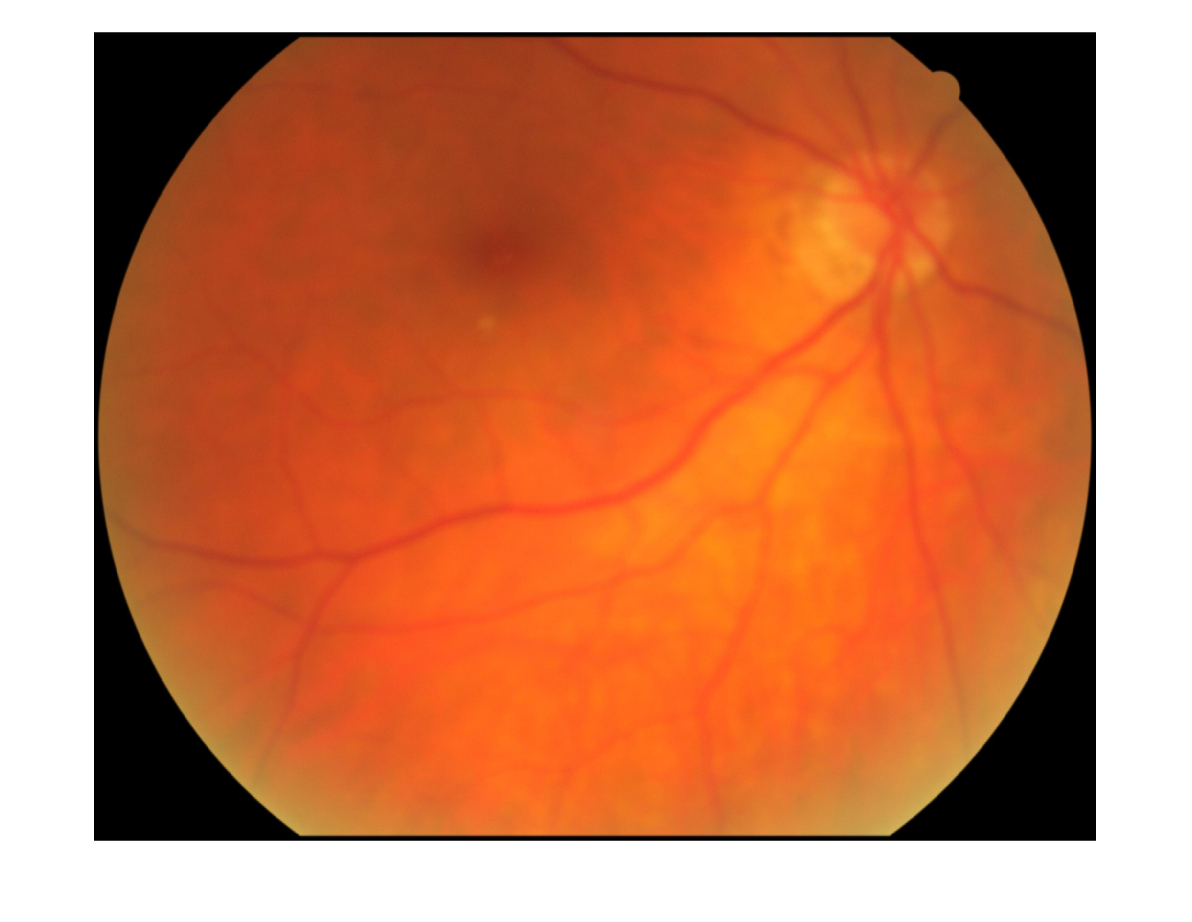

close all
clear
metadata=readtable("metadata.csv");

[im_sin,~,~] = find(metadata.quality==0);
sin = metadata(im_sin,:);
RAN=randi([1,height(sin)]);

im_sin_str = string(sin.image(RAN));
I= imread(im_sin_str);

figure
imshow(I,[])

% HOGfeatures_limp = extractHOGFeatures(rgb2gray(I));
% LBPfeatures_limp = extractLBPFeatures(rgb2gray(I));
% ORBfeatures_limp = detectORBFeatures(rgb2gray(I));

% SE=strel('disk',300);
% I2=imtophat(rgb2gray(I),SE);
% figure
% imshow(I2,[])
% I3=I2(266:height(I2)-266,348:length(I2)-348);
% I3(I3 < max(I2(:))/4)=0;
% level = graythresh(I3);
% I4 = imbinarize(I3,level);
% I5=I3.*uint8(I4);
% I5=imclose(I5,ones(6));
% figure
% imshow(double(I5),[])

% SE=strel('disk',100);
% 
% level = graythresh(I(:,:,1));
% B=imbinarize(I(:,:,1),level);
% I2=uint8(B).*I(:,:,1);
% 
% figure
% imshow(I2,[])
% 
% [hI, wI, ~] = size(I2);
% h=1;
% suma=0;
% while h<(hI-400)
%     l=1;
%     while l<(wI-400)
%         if suma<sum(sum(I2(h:h+400,l:l+400)))
%             suma=sum(sum(I2(h:h+400,l:l+400)));
%             ls=l;
%             hs=h;
%         end
%         l=l+50;
%     end
%     h=h+50;
% end
% 
% nerv=I(hs:hs+400,ls:ls+400,:);
% nervg=rgb2gray(nerv);
% figure
% imshow(nerv,[])

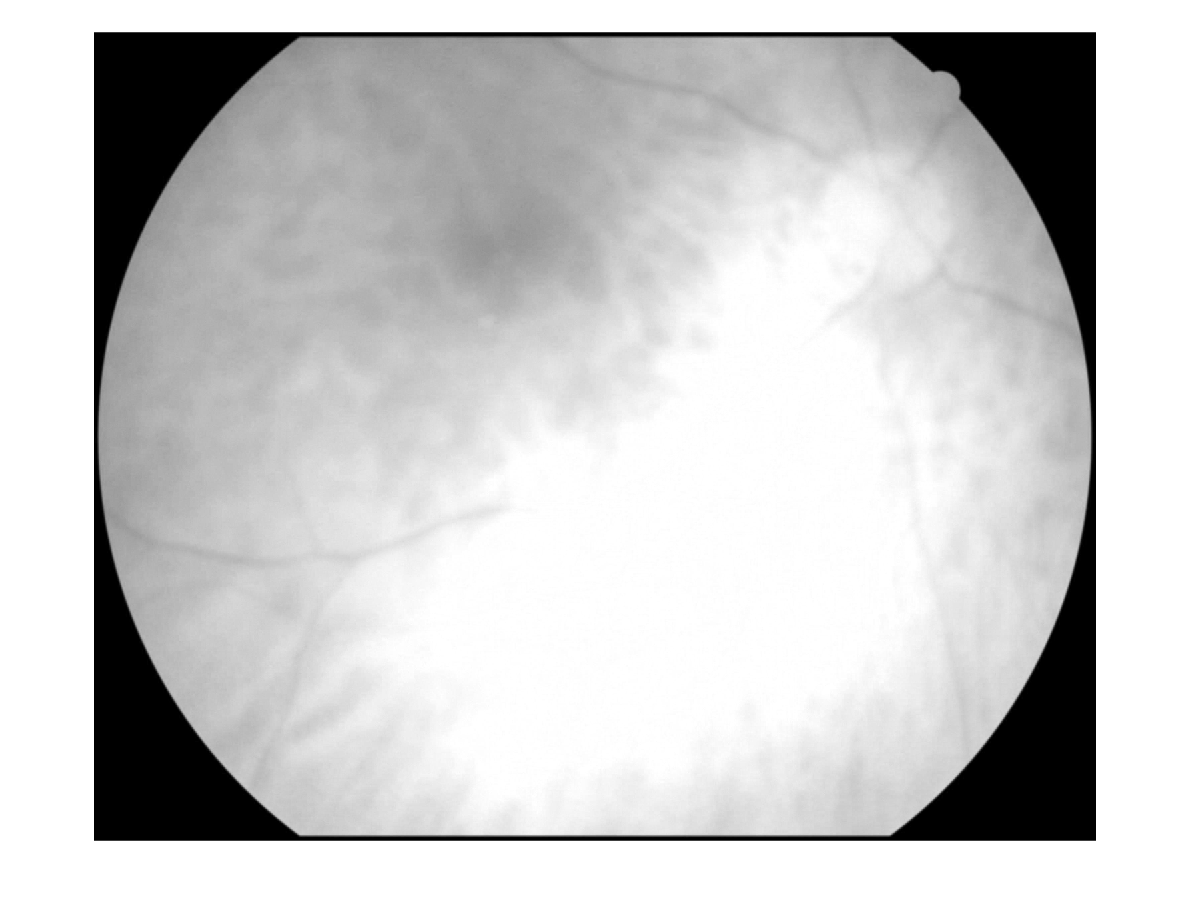

figure
imshow(I(:,:,1))

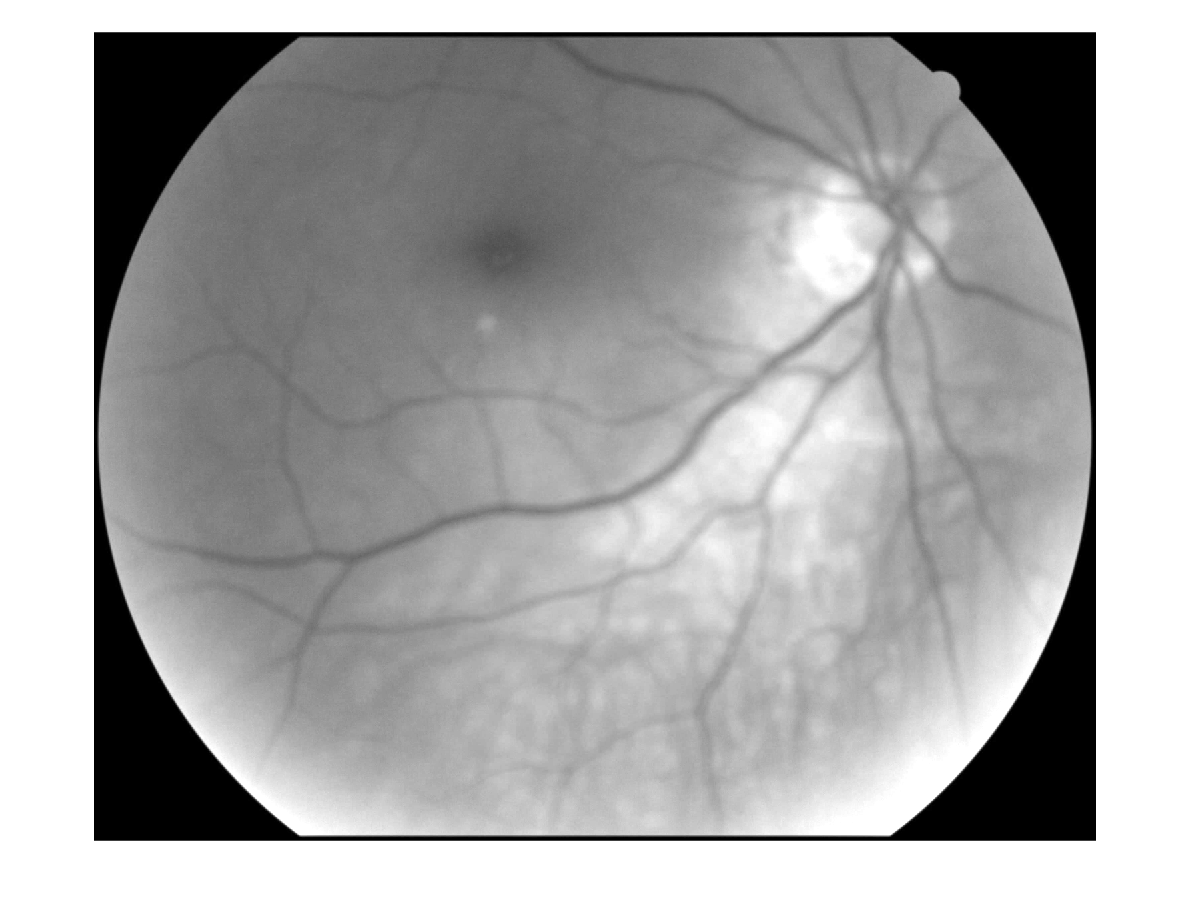

if mean(mean(I(:,:,1)))>170
%     r=0:255;
%     gamm=35;
%     s=((256-1)/(256-1)^gamm)*r.^gamm;
%     I4=interp1(r,s,double(I(:,:,1)));
    I4=I(:,:,2);
else
    I4=I(:,:,1);
end

I4=imadjust(I4);
figure
imshow(I4,[])

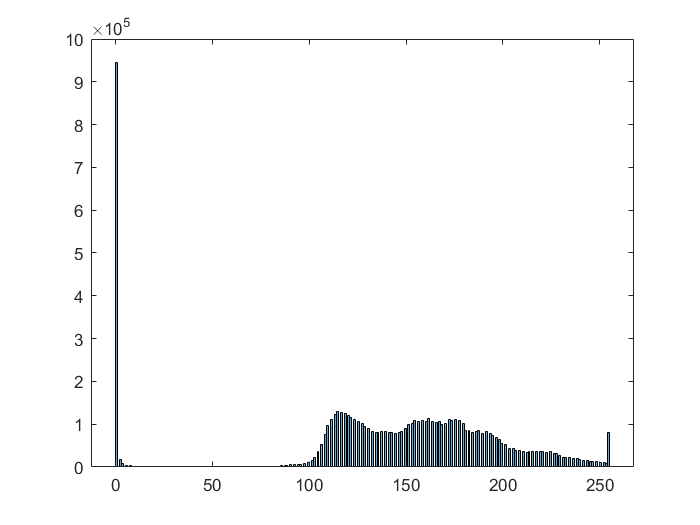

figure
histogram(I4)

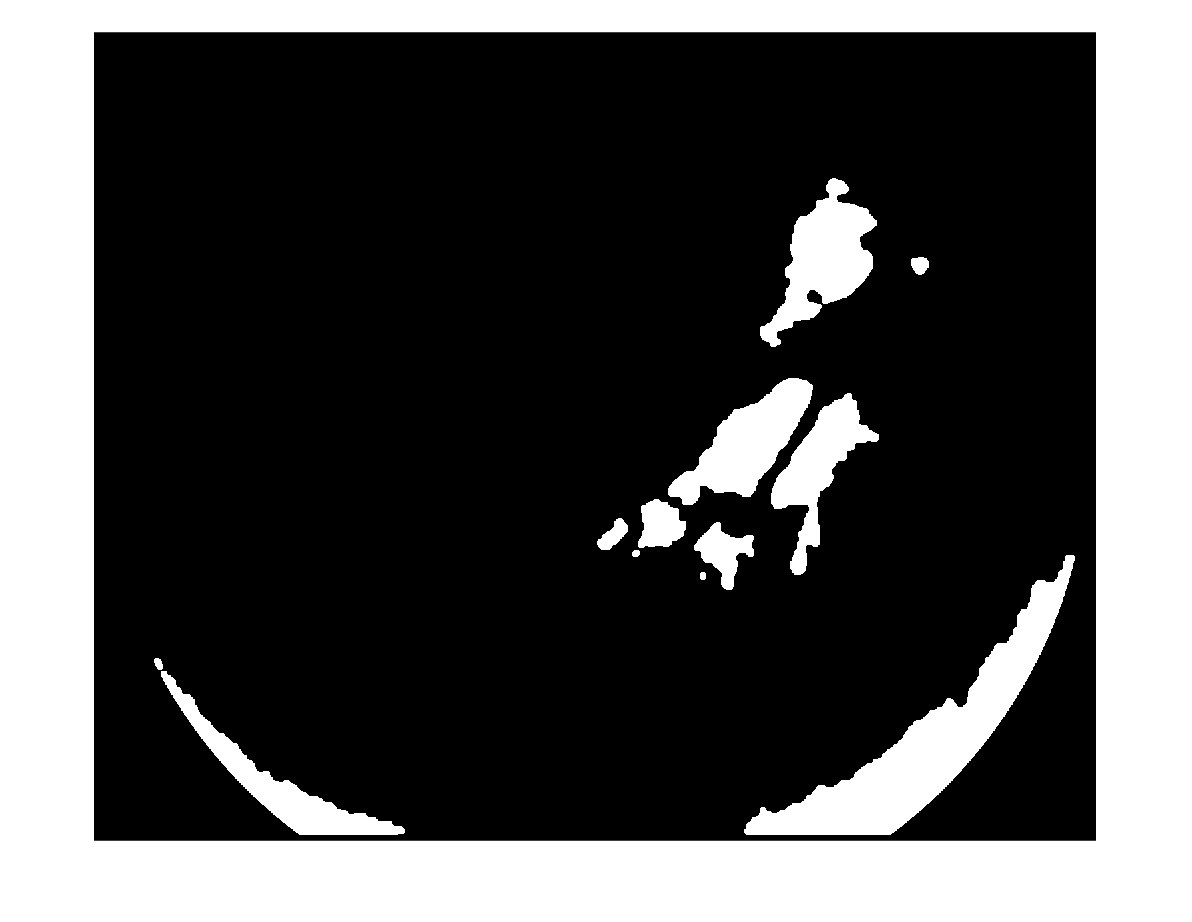


SE2=strel('disk',10);

H=I4>220;
if mean(mean(I(:,:,1)))>170
    Hc=imclose(H,SE2);
    Hc=imopen(Hc,SE2);
else
    Hc=imopen(H,SE2);
end


[labeledImg n] = bwlabel(Hc,8);

figure
imshow(labeledImg)

n

n = 12


statsd = regionprops(labeledImg,'Circularity','Centroid',"Area","BoundingBox");
dotcirc = cat(1,statsd.Circularity);
dotcentr = cat(1,statsd.Centroid);
dotarea = cat(1,statsd.Area);
dotbox = cat(1,statsd.BoundingBox);
dotarea = dotarea/max(dotarea);
L=0; %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% MIRAR AREA PRIMERO
x = 1;
for i = 1:height(dotarea)
    if dotarea(i) < 0.5
        L(x) = i;
        x = x+1;
    end
end
dotarea(dotarea<0.5) = [];

if L~=0
    dotcentr(L,:) = [];
    dotcirc(L,:) = [];
    dotbox(L,:) = [];
end
[~,idx] = max(dotcirc)

idx = 1

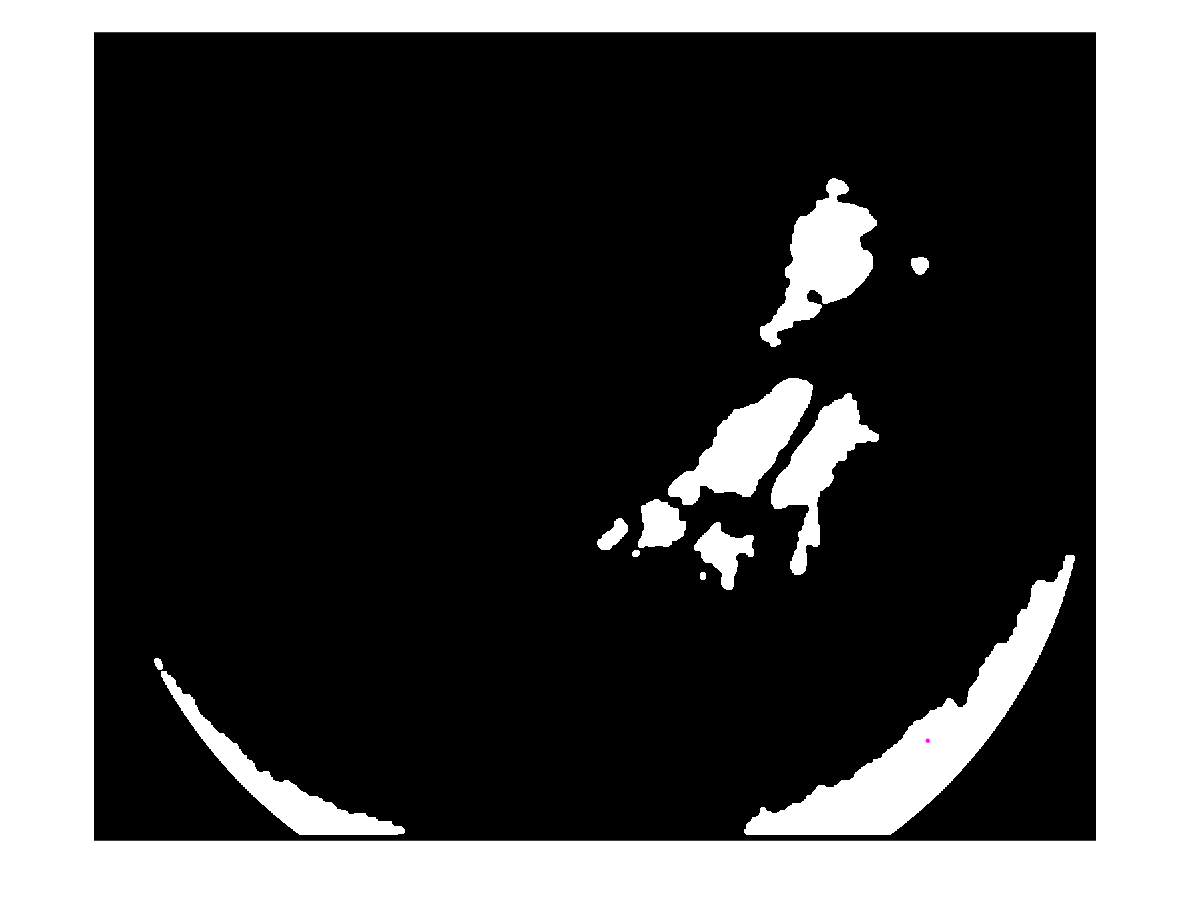


figure
imshow(labeledImg)
hold on
plot(dotcentr(idx,1),dotcentr(idx,2),'.m','MarkerSize',8);
hold off


CooX1=dotcentr(idx,2)-250;
CooX2=dotcentr(idx,2)+250;
CooY1=dotcentr(idx,1)-250;
CooY2=dotcentr(idx,1)+250;

if CooX1<1
    CooX1=1;
end
if CooX2>height(I)
    CooX2=height(I);
end
if CooY1<1
    CooY1=1;
end
if CooY2>length(I)
    CooY2=length(I);
end


figure
nerv=I(CooX1:CooX2,CooY1:CooY2,:);

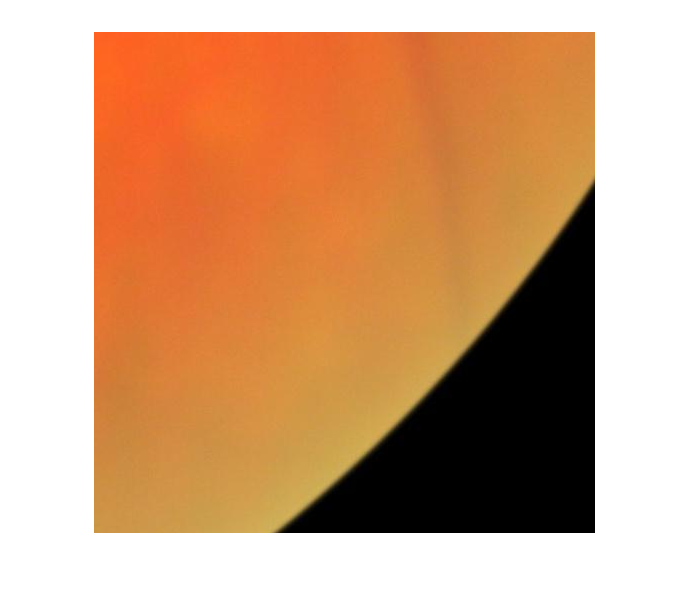

imshow(nerv,[])

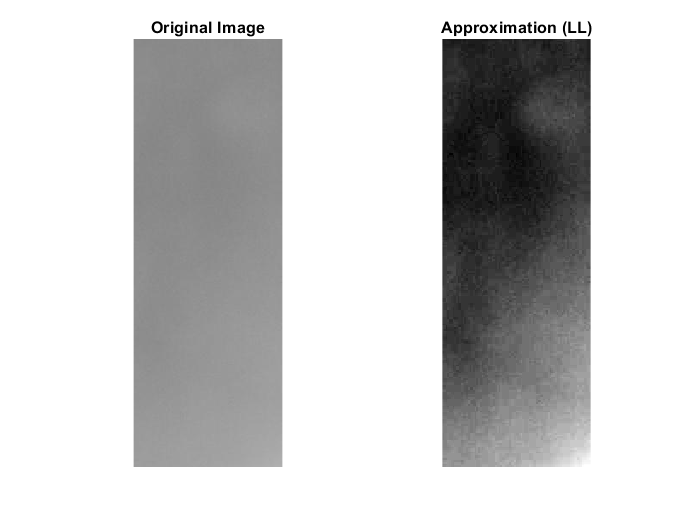

% SE2=strel('disk',20);
% level = graythresh(nervg);
% G=imbinarize(nervg,level);
% Gd=double(G)*0.5;
% Gd=imclose(Gd,SE2);
% R=imbinarize(nervg,level+(1-level)/2);
% Rd=double(R)*0.5;
% Rd=imclose(Rd,SE2);
% Fd=Gd+Rd;
% figure
% subplot(131)
% imshow(Gd,[])
% subplot(132)
% imshow(Rd,[])
% subplot(133)
% imshow(Fd,[])
% nervmasc=uint8(Fd).*nerv(:,:,:);
% figure
% imshow(nervmasc,[]);
% nervg=rgb2gray(nerv);
% 
% [LL, LH, HL, HH] = dwt2(nervg, 'db1');
% 
% figure
% subplot(1, 2, 1);
% imshow(nervg);
% title('Original Image');
% 
% subplot(1, 2, 2);
% imshow(LL, []);
% title('Approximation (LL)');